The explosion at the T2 plant occurred during the synthesis of sodium salt of methylcyclopentadiene:


$$2\mathrm{Na}+2\;C_5 H_6 \to 2\;\mathrm{Na}{\mathrm{C}}_5 {\mathrm{H}}_5 +H_2$$


The reactor was filled with methylcyclopentadiene dimer dissolved in diglyme, sodium was added, and then the reaction mixture was heated to 422K. After reaching this temperature, the heating was turned off, the reaction mixture heated up spontaneously to 455.4K, then the operator started cooling - a stream of tap water, which was heated to the boiling point, maintaining a constant temperature of 373.15K in the cooling jacket. On the day of the accident, the cooling did not start, the temperature began to rise, resulting in an increase in the reaction rate and intense hydrogen production. At some point, the applied safety system was not able to maintain the assumed constant hydrogen pressure in the reactor, equal to 4.4 atm. The temperature continued to rise and the diglyme reacted violently with sodium:


$$CH_3 \mathrm{OC}{\mathrm{H}}_2 C{\mathrm{H}}_2 \mathrm{OC}{\mathrm{H}}_2 C{\mathrm{H}}_2 \mathrm{OC}{\mathrm{H}}_3 +\mathrm{Na}\to 3H_2 +\mathrm{Side}\;\mathrm{Products}\left(g\right)\left(l\right)$$


The reaction accelerated and increased the pressure, which rose above 28.2 atm (the opening pressure of the safety valve). Since the rate of hydrogen production was faster than the rate at which it could be removed from the reactor through a four-inch valve tube, an explosion occurred. The reactor will explode when it reaches a temperature of 600 K or a pressure of 45 atm.

**Task:** Describe the concentration of methylcyclopentadiene, sodium and diglyme, the pressure of the surface phase in the reactor and the temperature of the reaction mixture from the moment of reaching the temperature of 422K to the moment of explosion (assume the time of 4 hours).

- Case 1: FD < 11400; Fv=FD

- Case 2: FD > 11400; p<28.8 atm; FV = (p-1)*CV1

- Case 3: P>=28.8atm;FV = (p-1)*(CV1 + CV2)

A1 = [dm3 · mol − 1 · h − 1] pre-exponential factor for reaction 1

A2 = [h − 1] pre-exponential factor for the reaction

CA0 = [mol · dm − 3] initial concentration of methylcyclopentadiene

CB0 = [mol · dm − 3] initial sodium concentration

CI0 = [mol · dm − 3] initial concentration of inerts

CS0 = [mol · dm − 3] diglyme initial concentration

Cv1 = [mol · atm − 1 · h − 1] ventilation rate for P <28.2 atm

Cv2 = [mol · atm − 1 · h − 1] ventilation rate for P 28.2 atm

E1 = [kJ · mol − 1] activation energy of reaction 1

E2 = [kJ · mol − 1] activation energy of reaction 2

Fv = [mol · h − 1] ventilation rate through the valve 4.4 atm

k1 - reaction rate constant 1 [dm3 · mol-1 · s-1]

k2 - reaction rate constant 2 [1 / s]

r - reaction rate [mol · s-1 · dm-3]

SW - switch

T - temperature [K]

V0 = [dm3] liquid volume in the reactor

VH = [dm3] volume of the headspace (gas) phase in the reactor

ΔH1 = [kJ · mol − 1] heat of reaction 1

ΔH2 = J · mol − 1] heat of reaction 2

ΔNiCpi [= [J · K − 1] the resultant molar heat of the mixture

Subscripts:

A - methylcyclopentadiene,

B - sodium,

D - hydrogen,

S - diglim

H - "in phase above the surface"

V - ventilation

## Parameters

Fv=11400:               % mol/h

-r1=k1CACB

-r2=k2CS

CV1 = 3360;             % [mol *atm-1 * h-1]

CV2 = 53600;            % [mol *atm-1 * h-1]

k1 = 4*10^14;           % exp(-128000/RT)

k2 = 4*10^84 exp(-800000/RT);

Cv1 = 3360;             % mol*atm-1*h-1

Cv2 = 53600;            % mol*atm-1*h-1

A1 = 4*10^14;           % dm3mol-1h-1

E1 = 128;               % kJ*mol-1

ΔH1 = -45.4;            % kJ*mol-1

A2 = 1084;              % h-1

E2 = 800;               % kJ*mol-1

ΔH2 = 3.2*10^5;         % kJ*mol-1

CA0 =4.3;               % mol*dm3

CD0 =5.1;               % mol*dm3

CI0 =0.088;             % mol*dm3

CS0 =3;                 % mol*dm3

V0 = 4000;              % dm3

VH = 5000;              % dm3

ΣNi*Cpi=1.26*10^7;      % J*K-1

## Equations


$$\begin{array}{l}
r_1 =-k_1 C_A C_B \\
r_2 =-k_2 C_S \\
\frac{d}{\textrm{d}t}C_A =r_1 \\
\frac{d}{\textrm{d}t}C_B =r_1 \\
\frac{d}{\textrm{d}t}C_S =r_2 \\
\frac{d}{\textrm{d}t}N_D =F_D -F_V \\
F_D =\left(-0\ldotp 5r_1 -3r_2 \right)V_0 \\
N_D =\frac{{\mathrm{PV}}_H }{{\mathrm{RT}}_H }\\
\frac{d}{\textrm{d}t}P=\left(F_D -F_V \right)\;\frac{{\mathrm{RT}}_H }{V_H }\;\\
\frac{d}{\textrm{d}t}T=\;\frac{V_0 {\left(r_1 ∆{\mathrm{H}}_1 +r_2 ∆{\mathrm{H}}_2 \right)}-UA\left(T-T_1 \right)}{\Sigma \left({\mathrm{N}}_i C{\mathrm{p}}_i \right)}
\end{array}$$


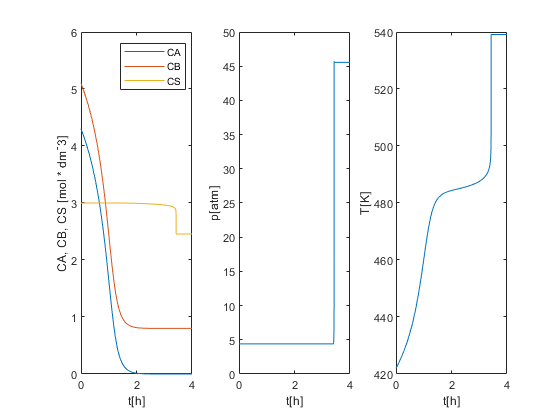

[t,x]=ode45(@Reaction, [0 4], [4.3 5.1 3 4.4 422]);
 

plot(t,x(:,1),t,x(:,2),t,x(:,3))
xlabel('t[h]')
ylabel('CA, CB, CS [mol * dm^-3]')
legend('CA','CB','CS')

plot(t,x(:,4))
xlabel('t[h]')
ylabel('p[atm]')

plot(t,x(:,5))
xlabel('t[h]')
ylabel('T[K]')

function dxdt=Reaction(t,x)
CA=x(1);
CB=x(2);
CS=x(3);
p=x(4);
T=x(5);
R=8.314;
V0=4000;
VH=5000;

DH1=-45400;
DH2=-3.2e5;
sumaNCp=1.26e7;
k1=4e14 *exp(-128000/(R*T));
k2=1e84 *exp(-800000/(R*T));
r1=-k1*CA*CB;
r2=-k2*CS;
FD=(-0.5*r1-3*r2)*V0;
CV1=3360;
CV2=53600;
 
 
if FD <11400
    Fv=FD;
else
    if p<45
        Fv = (p-1)*CV1;
    else
        Fv = (p-1)*(CV1+CV2);
    end
end
 
 
if T>600
    SW = 0;
elseif p>45
    SW = 0;
else
    SW = 1;
end
 
dxdt=[SW*r1;
    SW*r1;
    SW*r2;
    SW*((FD-Fv)*0.082*T/VH);
    SW*(V0*(r1*DH1+r2*DH2))/sumaNCp];
end